# K-Means and P-Median Clustering

In questo breve report andiamo a valutare i clusters ottenuti utilizzando due diversi algoritmi. Il dataset è visto come un grafo, in cui ciascun nodo è un elemento del dataset e il peso di ogni arco rappresenta la distanza euclidea tra i nodi che congiunge. Dopo aver effettuato il clustering, i nodi sono suddivisi in più classi (i clusters) e per ognuna di esse è possibile calcolare la somma dei pesi degli archi incidenti in nodi contenuti al suo interno. Il costo della partizione è quindi dato dalla somma dei valori ottenuti. In questo senso, confrontiamo i partizionamenti ottenuti risolvendo il problema di clustering con K-Means e sfruttando la sua formulazione come problema di P-Mediana (sugli stessi dataset). L'implementazione di [K-Means](https://it.mathworks.com/help/stats/kmeans.html) è quella fornita dal Matlab, mentre il modello di PLI è stato risolto mediante l'euristica di Teitz e Bart implementata in Python.

Di seguito i valori ottenuti con Teitz e Bart su un dataset di 100 elementi con un numero di cluster desiderato pari a 10.

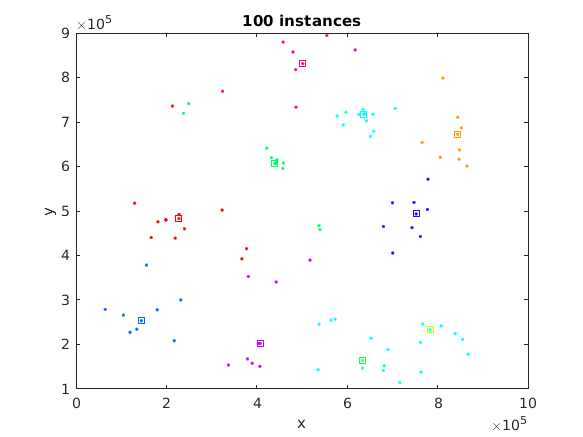

% dataset: dataset contenente i punti su cui effettuare il clustering
dataset = importdata("dataset/s-set2_100.arff");

% idx_p_median: matrice contenente le associazioni punti - cluster ricavati 
% con script Python. La terza colonna di questa matrice contiene i cluster 
% a cui appartengono i punti.
idx_p_median = xlsread('p_median/array/array_100.xlsx');

% centroids: matrice ricavata con script Python che contiene i punti (x,y) che 
% sono stati scelti come centroidi.
centroids = xlsread('p_median/centroids/centroids_100.xlsx');

tot_p_median = 0;
for i=1:10
    
    % dataset.data(find(idx_p_median(:,3)==i),:) : seleziona tutti i punti 
    % del dataset che sono stati associati al cluster i
    tot_p_median = tot_p_median + sum(pdist(dataset.data(find(idx_p_median(:,3)==i),:)));
end

% effettua il plot dei risultati del clustering, evidenziando con dei quadrati 
% vuoti i centroidi individuati
PlotClusters(dataset.data,idx_p_median(:,3),centroids,100);

tot_p_median

tot_p_median = 1.8509e+08

Come si può notare i punti selezionati come centroidi coincidono con punti appartenenti al dataset.

Di seguito i valori ottenuti con K-Means su un dataset di 100 elementi con un numero di cluster desiderato pari a 10.

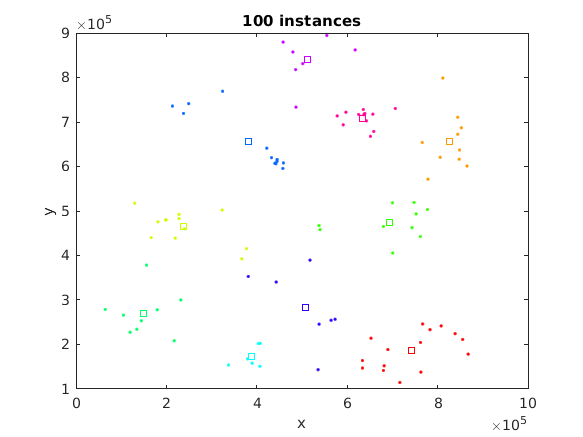

dataset = importdata("dataset/s-set2_100.arff");

% kmeans : funzione matlab che restituisce i risultati del clustering
% effettuato su un dataset in ingresso, fornendo il numero di cluster desiderato.
% idx_k_means : vettore di indici, indica le associazioni punti - cluster.
% centroids : punti (x,y) che sono stati individuati come centroidi .
[idx_k_means, centroids] = kmeans(dataset.data,10);
tot_k_means = 0;
for i=1:10
    tot_k_means = tot_k_means + sum(pdist(dataset.data(find(idx_k_means==i),:)));
end
PlotClusters(dataset.data,idx_k_means,centroids,100);

tot_k_means

tot_k_means = 4.8503e+07

Come si può notare i punti selezionati come centroidi possono anche non coincidere con punti appartenenti al dataset.

Di seguito i valori ottenuti con Teitz e Bart su un dataset di 200 elementi con un numero di cluster desiderato pari a 10.

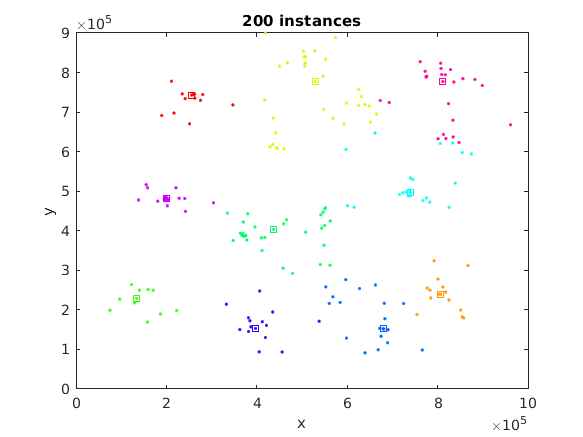

dataset = importdata("dataset/s-set2_200.arff");
idx_p_median = xlsread('p_median/array/array_200.xlsx');
centroids = xlsread('p_median/centroids/centroids_200.xlsx');
tot_p_median = 0;
for i=1:10
    tot_p_median = tot_p_median + sum(pdist(dataset.data(find(idx_p_median(:,3)==i),:)));
end
PlotClusters(dataset.data,idx_p_median(:,3),centroids,200);

tot_p_median

tot_p_median = 2.3506e+08

Di seguito i valori ottenuti con K-Means su un dataset di 200 elementi con un numero di cluster desiderato pari a 10.

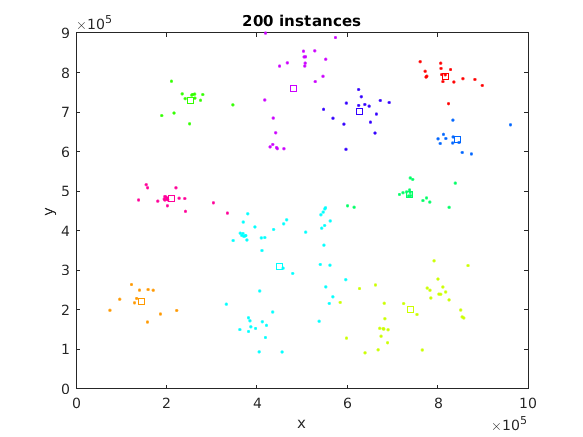

dataset = importdata("dataset/s-set2_200.arff");
[idx_k_means, centroids] = kmeans(dataset.data,10);
tot_k_means = 0;
for i=1:10
    tot_k_means = tot_k_means + sum(pdist(dataset.data(find(idx_k_means==i),:)));
end
PlotClusters(dataset.data,idx_k_means,centroids,200);

tot_k_means

tot_k_means = 3.3584e+08

Di seguito i valori ottenuti con Teitz e Bart su un dataset di 300 elementi con un numero di cluster desiderato pari a 10.

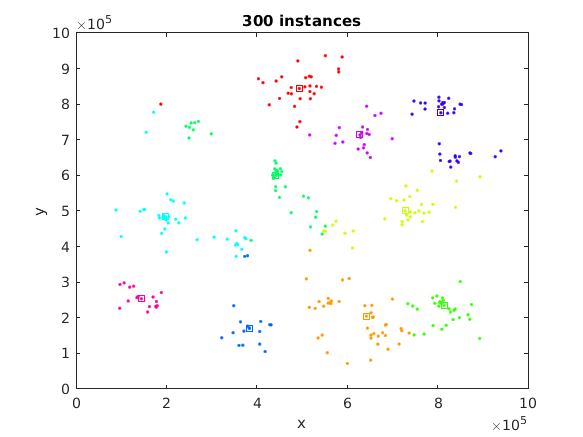

dataset = importdata("dataset/s-set2_300.arff");
idx_p_median = xlsread('p_median/array/array_300.xlsx');
centroids = xlsread('p_median/centroids/centroids_300.xlsx');
tot_p_median = 0;
for i=1:10
    tot_p_median = tot_p_median + sum(pdist(dataset.data(find(idx_p_median(:,3)==i),:)));
end
PlotClusters(dataset.data,idx_p_median(:,3),centroids,300);

tot_p_median

tot_p_median = 5.1239e+08

Di seguito i valori ottenuti con K-Means su un dataset di 300 elementi con un numero di cluster desiderato pari a 10.

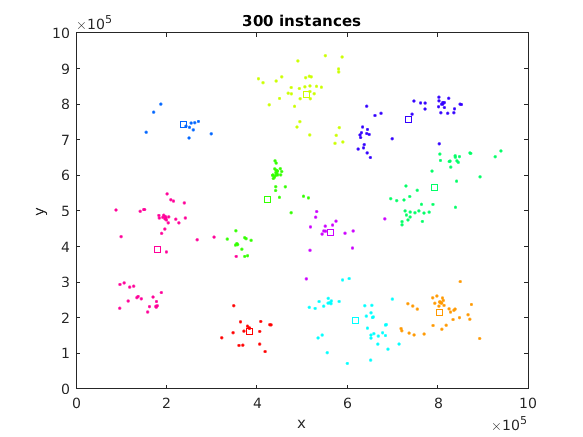

dataset = importdata("dataset/s-set2_300.arff");
[idx_k_means, centroids] = kmeans(dataset.data,10);
tot_k_means = 0;
for i=1:10
    tot_k_means = tot_k_means + sum(pdist(dataset.data(find(idx_k_means==i),:)));
end
PlotClusters(dataset.data,idx_k_means,centroids,300);

tot_k_means

tot_k_means = 5.5835e+08

Di seguito i valori ottenuti con Teitz e Bart su un dataset di 400 elementi con un numero di cluster desiderato pari a 10.

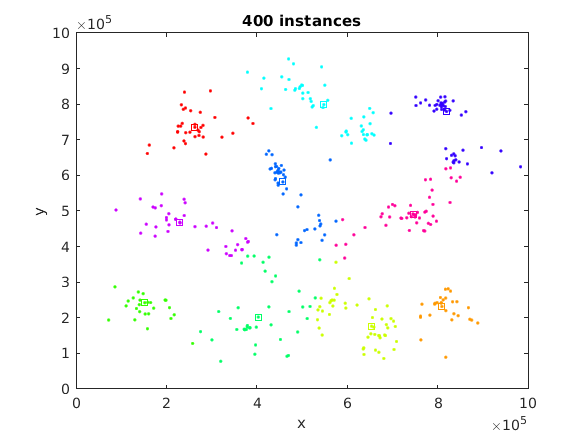

dataset = importdata("dataset/s-set2_400.arff");
idx_p_median = xlsread('p_median/array/array_400.xlsx');
centroids = xlsread('p_median/centroids/centroids_400.xlsx');
tot_p_median = 0;
for i=1:10
    tot_p_median = tot_p_median + sum(pdist(dataset.data(find(idx_p_median(:,3)==i),:)));
end
PlotClusters(dataset.data,idx_p_median(:,3),centroids,400);

tot_p_median

tot_p_median = 8.5940e+08

Di seguito i valori ottenuti con K-Means su un dataset di 400 elementi con un numero di cluster desiderato pari a 10.

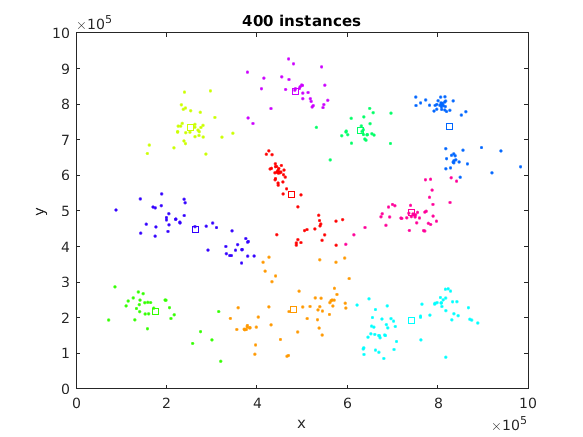

dataset = importdata("dataset/s-set2_400.arff");
[idx_k_means, centroids] = kmeans(dataset.data,10);
tot_k_means = 0;
for i=1:10
    tot_k_means = tot_k_means + sum(pdist(dataset.data(find(idx_k_means==i),:)));
end
PlotClusters(dataset.data,idx_k_means,centroids,400);

tot_k_means

tot_k_means = 8.9420e+08